load lineup.mat;
sound(y,8192);

1) Listen to the speech file. Describe what you hear. Make a plot of y[n]. Given the sampling rate of 8192 Hz, what is the duration in seconds of the audio signal? In equation 1 y[n] = x[n]+ax[n-N], what do each of the variables represent? Explain how equation 1 models the signal of speech with an echo.

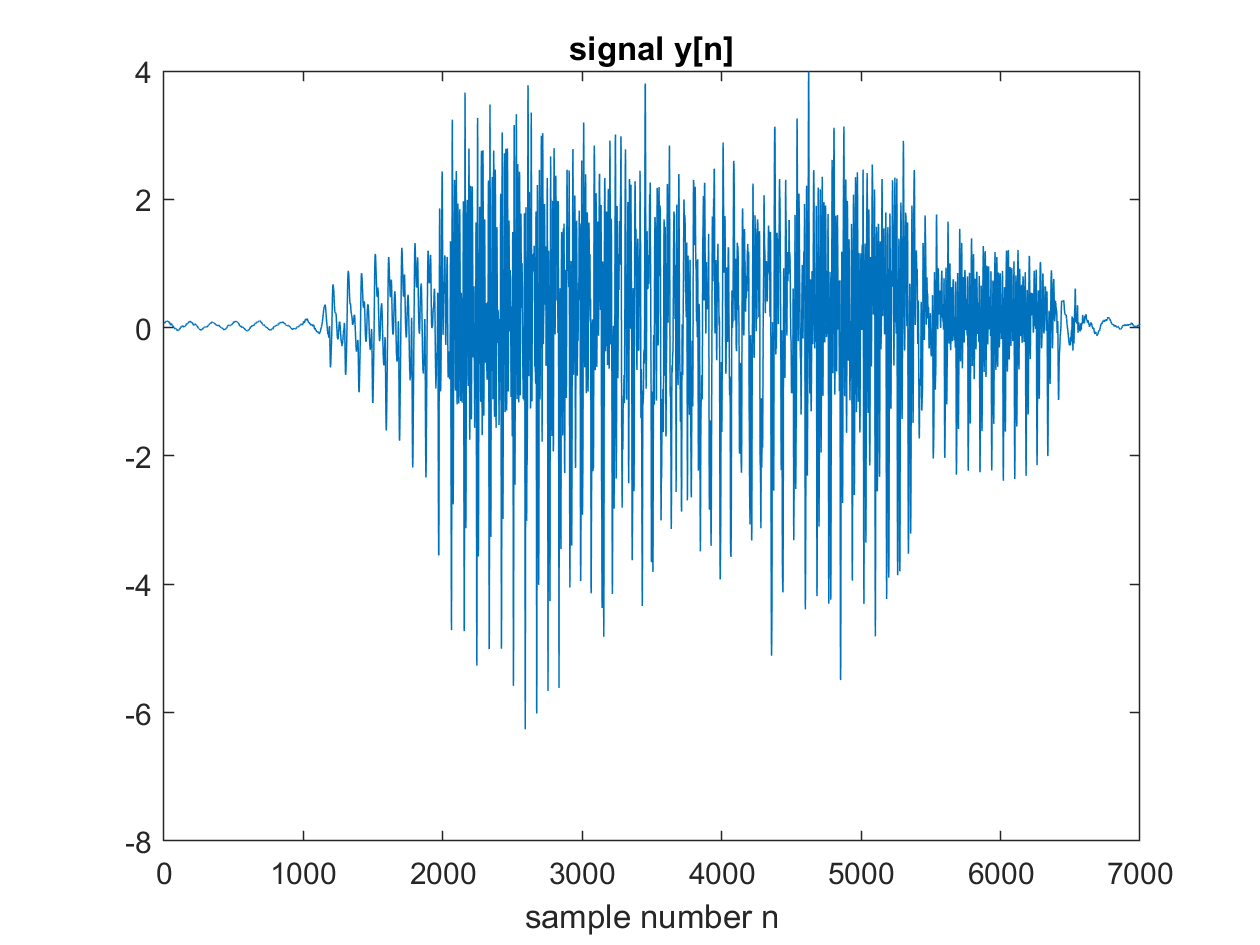

plot(y);
title('signal y[n]');
xlabel('sample number n');

2) Since the echo can be represented by a linear system of the form of equation 1, determine and plot the impulse response of the echo system. Store this impulse response in the vector h[n] for 0</= n </=1000 and plot h[n]. Explain your plot of h[n], including why it makes sense and how it is consistent with equation 1.

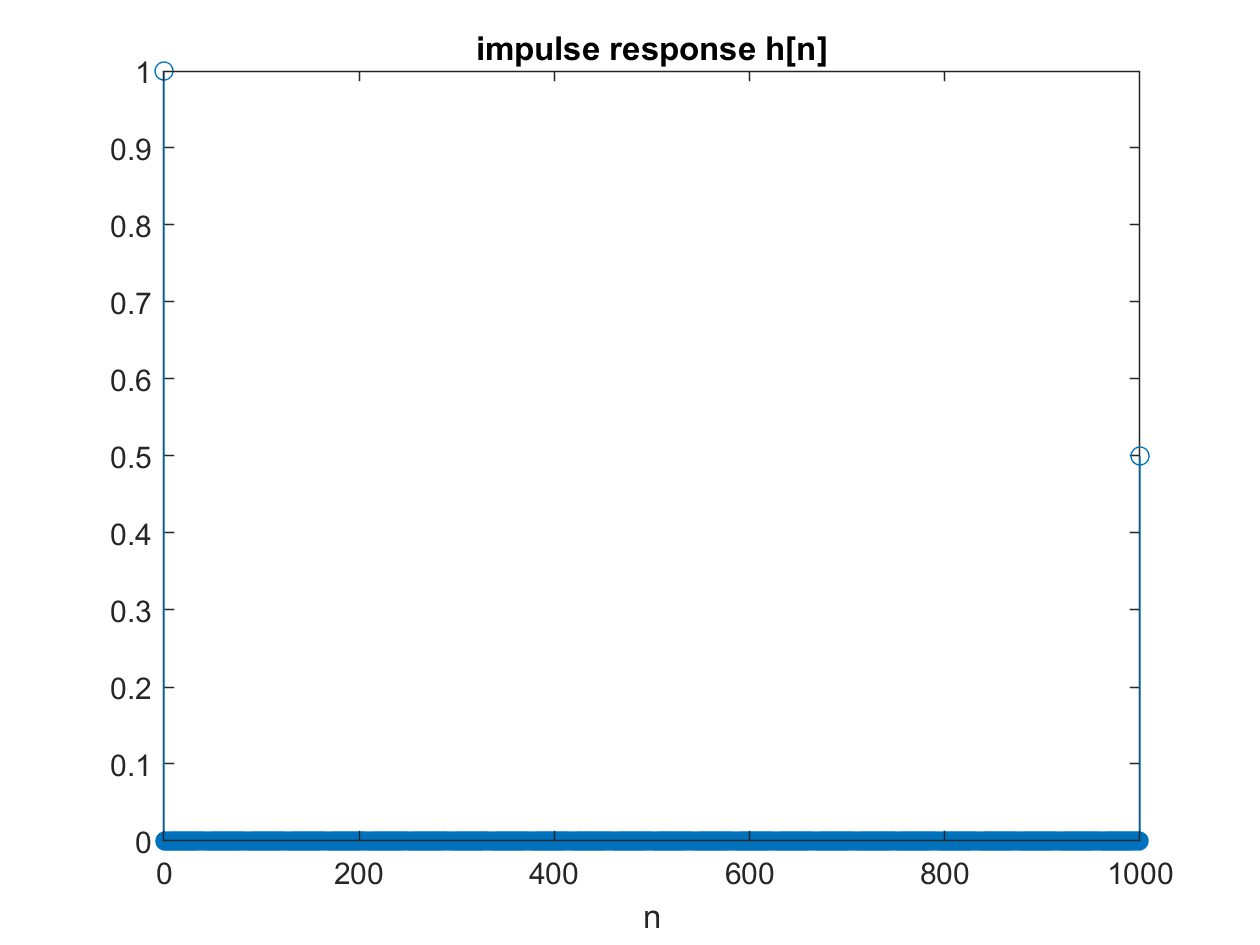

nh = [0:1000];
h = [1 zeros(1,999) 0.5];
stem(nh,h);
title('impulse response h[n]');
xlabel('n');

3) Consider an exho removal system described by the difference equation z[n]+az[n-N]=y[n] where y[n] is the input and z[n] is the output which has the echo removed. Refer to this system described by equation 2 as having the impulse response g[n].

Draw a diagram that relates equations 1 and 2 through x[n], y[n], z[n], h[n], and g[n]. In terms of your diagram, describe what is meant by an inverse system and describe how the echo could be removed in terms of h[n]*g[n].

4) Here you will determine and plot the impulse response g[n] of the echo removal system in equation 2 above. The system of equation 2 has an infinite-length impulse response and you will need to use the matlab function "filter" to compute the response to an impulse. Assuming that N=1000 and a=0.5, compute the impulse response, using the impulse response given by delta=[1 zeros(1,4000)]. Store this 4001 sample approximation to the impulse response in the vector g[n]. Plot this impulse response g[n] and describe your plot.

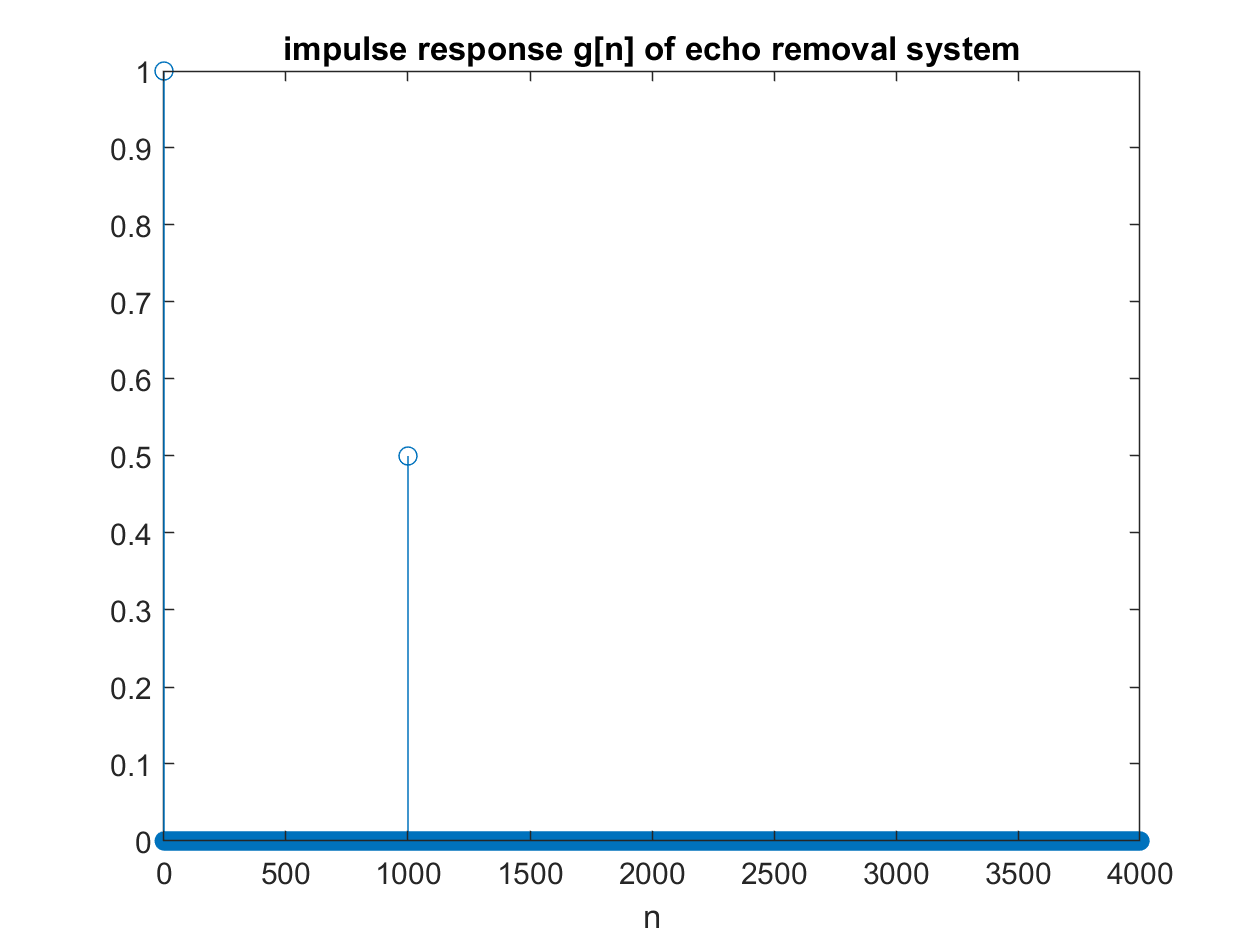

ng = [0:4000];
delta = [1 zeros(1,4000)];
g = filter(h,[1],delta);
stem(ng,g);
title('impulse response g[n] of echo removal system');
xlabel('n');

5) Implement the echo removal system using z=filter(B,A,y). Use y as an input to equation 2 described by g[n] and listen to the output z[n]. Do you still hear an echo? Make adjacent (upper and lower) plots that compare to the signals y[n] (lineup.mat) and z[n] (your output) and describe how the two differ and why. What do you notice about the echo?

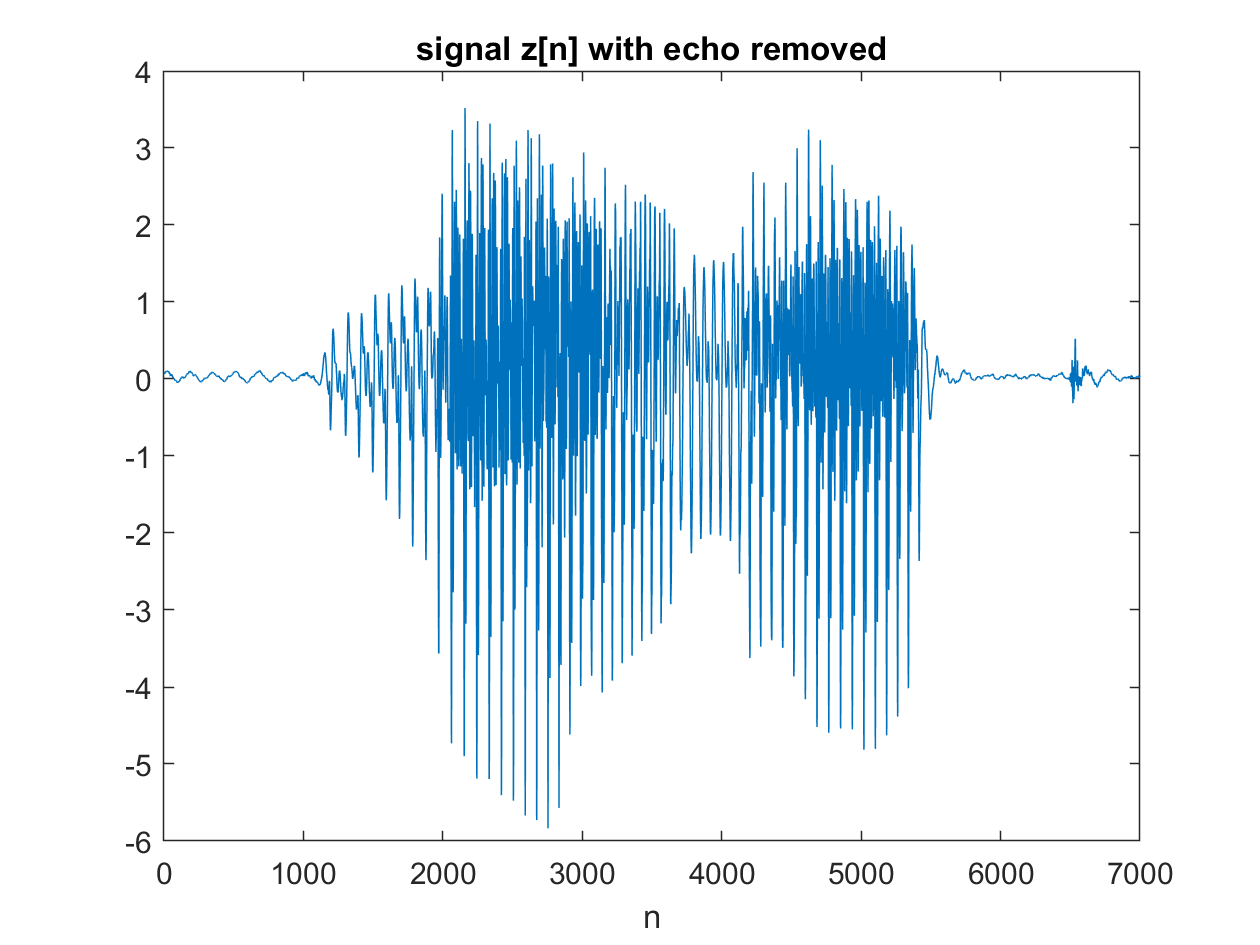

z = filter([1],g,y);

plot(z);
title('signal z[n] with echo removed');
xlabel('n');

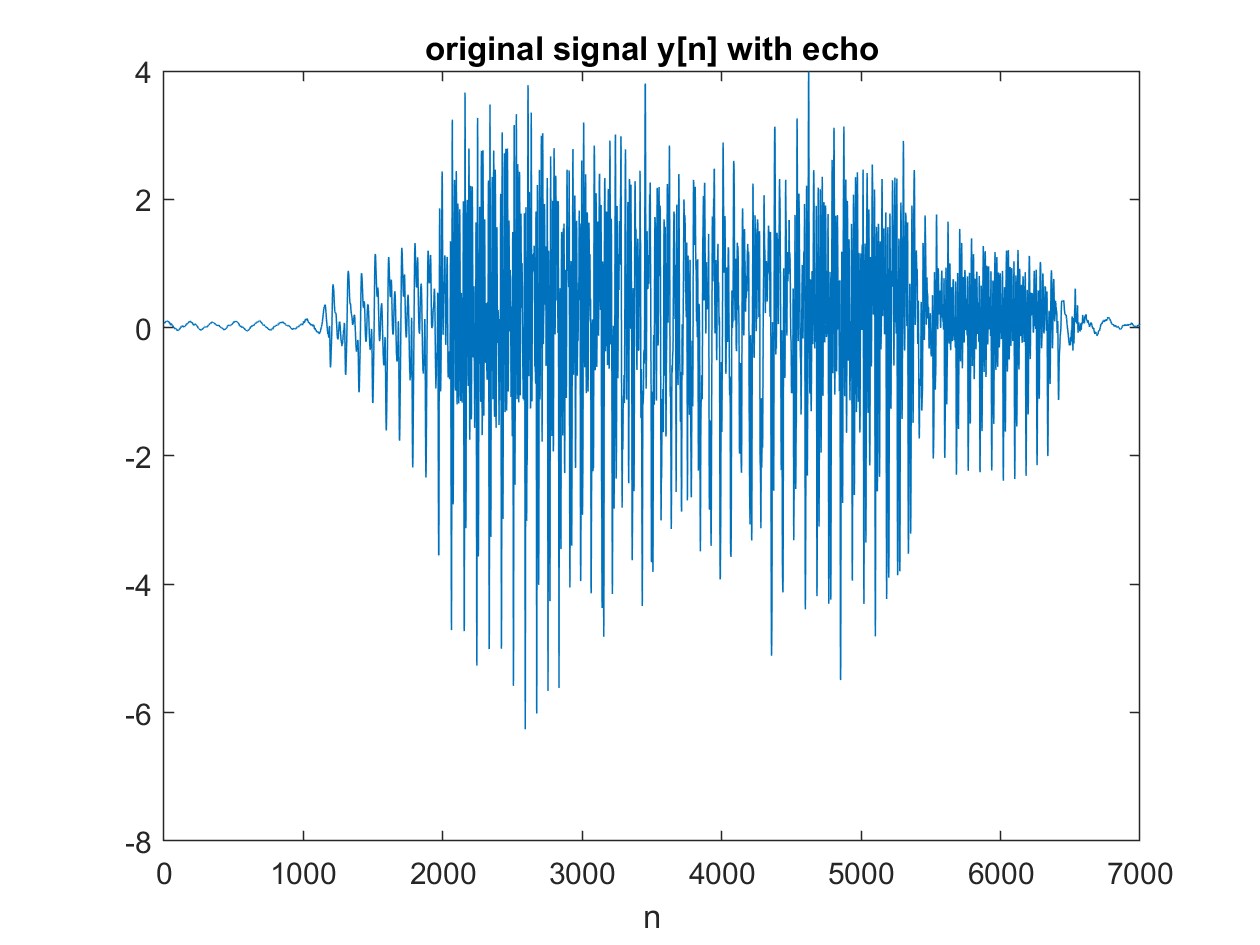


plot(y);
title('original signal y[n] with echo');
xlabel('n');


sound(z,8192);

6) Calculate in Matlab the overall impulse response of the cascaded echo system: k[n] = h[n] * g[n]. You can use the function "conv" here. Why might you expect k[n] to be a unit impulse? Why is k[n] not a unit impulse? is the system g[n] truly an inverse system? why or why not?

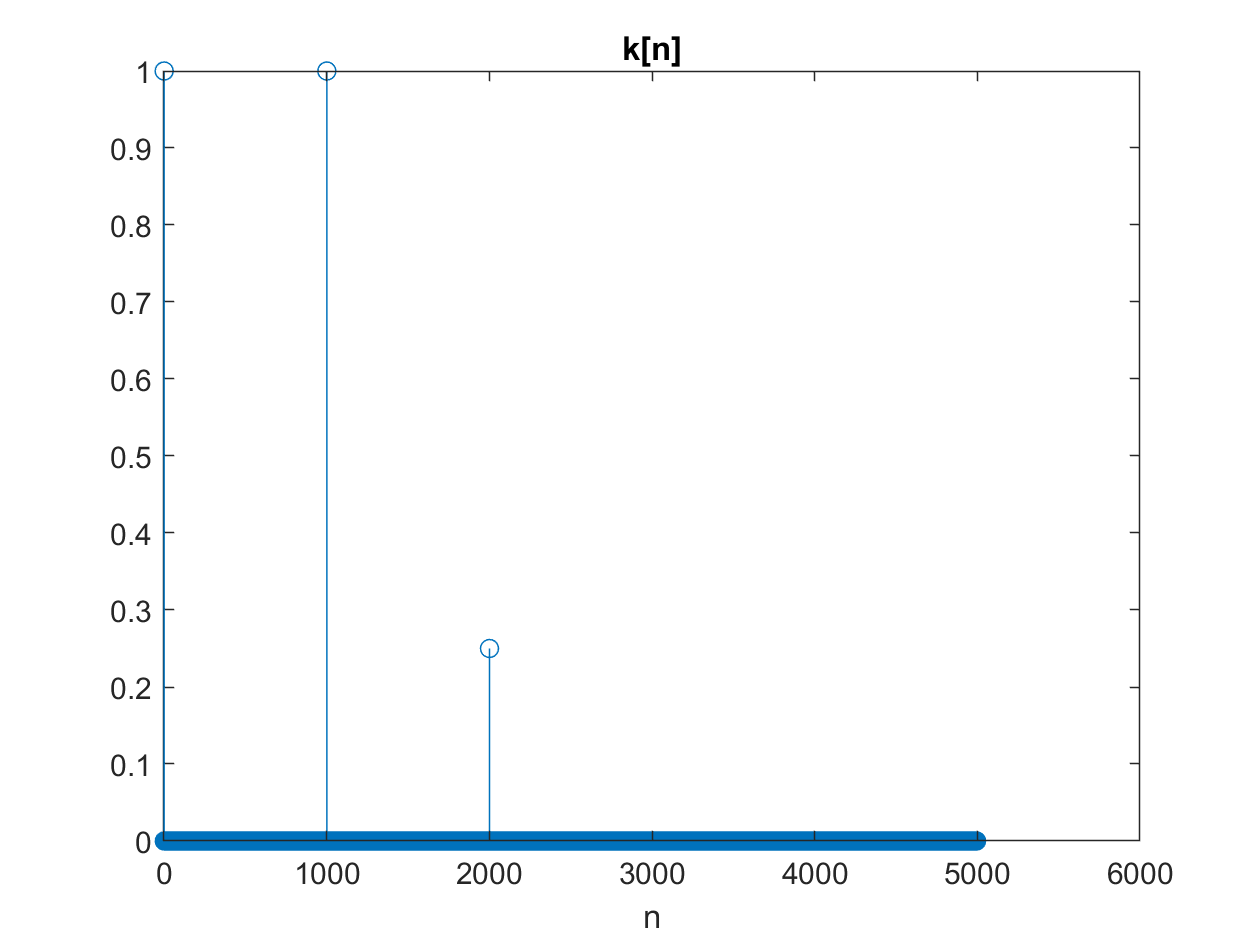

k = conv(h,g);
stem(k);
title('k[n]');
xlabel('n');